# Data Pre-Processing 

## Step 1: Download Data 

Data used in this example has been provided by the [Robotics Association at Embry-Riddle](https://www.roboticsassociation.org/about-us)'s RoboSub Team. The footage contains images clicked underwater at the TRANSSDEC in San Diego, CA during practice runs at the competition. The dataset can be downloaded from a google drive here : [RoboSubFootage](https://drive.google.com/drive/folders/1bhohhPoZy03ffbM_rl8ZUPSvJ5py8rM-)

Once you have downloaded the dataset, extract the contents of the zip file and add it to the current directory. Once added to the current directory, add `RoboSubFootage` and its subfolders to the path. This should look like this:

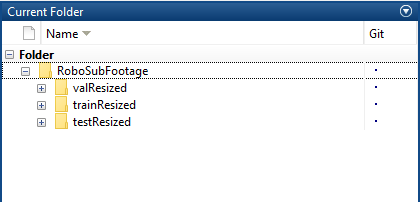

## Step 2: Image Resizing

Resize image to **416x416x3** to account for the YOLOv2 Architecture. For information on this click this [link](https://www.mathworks.com/help/vision/ug/getting-started-with-yolo-v2.html). **The dataset provided has already been resized to make it easier for sharing, this step needs to be done only if you are using your own data.** 

imageResizingNeeded = true;

if imageResizingNeeded
    folderName = "C:\Users\peanu\OneDrive - UNSW\20T2\MTRN4230\Group Project\Matlab testing\yolov2deeplearningtutorial\PNG Blue Cube\"; % Enter the name of the folder that holds your dataset
    
    %srcDir = fullfile(folderName)
    folder_name = uigetdir(folderName);
    srcFiles = dir(fullfile(folder_name,'*.png'));
    %srcFiles = dir([srcDir,'*.png']);
    for i = 1 : length(srcFiles)
        %filename = [srcDir ,srcFiles(i).name];
        filename = [folder_name,'\',srcFiles(i).name];
        im = imread(filename);
        k=imresize(im,[416,416]);
        %newfilename=[srcDir ,srcFiles(i).name];
        newfilename=[srcFiles(i).name];
        imwrite(k,newfilename,'jpeg');
    end
end

## Step 3: Split Folders

Split the validation dataset folder into 2, one for testing and one for validation. **The dataset provided is already split randomly using the code below, run this code if you are using your own dataset.**

splitFolder = true;


if splitFolder
    valFolderName = "RGBD_Data\PNG Blue Cube";
    
    files = dir(fullfile(valFolderName));
    N = length(files);
    tf=randperm(N)>(0.50*N);
    mkdir testResized;
    mkdir valResized;
    
    for i=3:length(tf)
        files_re = files(i).name;
        if tf(i) == 1
            copyfile (fullfile(valFolderName,files_re),'testResized')
        else
            copyfile (fullfile(valFolderName,files_re),'valResized')
        end
    end
end


## Step 4: Create Ground Truth

Use the Ground truth labeler app to label the objects of interest in the dataset. [Watch this 5-minute video to learn how to use the Ground Truth Labeler App](https://www.youtube.com/watch?v=V2e0cygY9Vg&t=16s)

isGroundTruthAvailable = false;

if isGroundTruthAvailable
    labelingSessionName = fullfile("Utilities","groundTruthLabelingSessionRoboSubResizedTrain.mat");
    groundTruthLabeler(labelingSessionName)

else
    groundTruthLabeler;
    

### Using custom automation algorithms

The built-in algoirthms in the Ground Turth Labeler app are generic feature detectors or interpolators, you can also integrate your own custom algoirthms containing detectors that are explicitly looking your objects of interest. [Watch this 5-minute video to learn how to use custom automation algorithms in MATLAB's labeler apps](https://www.youtube.com/watch?v=Y36D1fJZkT0) .

The `vision.labeler.AutomationAlgorithm` class enables you to define a custom label automation algorithm for use in the labeling apps. You can use the class to define the interface used by the app to run a custom automation algorithm. We will use a trained **ACF Object Detector** to identify objects of interest. To use the custom algorithm follow the steps below:

**Create an Object Detection Algorithm**: Train an ACF Dectector for each object class with a subset of the data-set. Remember that there needs to be a single ACF detector for each class and save them as individual MAT files. [Watch this video to learn more.](https://www.mathworks.com/videos/matlab-and-simulink-robotics-arena-using-ground-truth-for-object-detection-part-2-1539872956812.html)

**Create the automation folder**: Create a `+vision/+labeler/` folder in any folder on the MATLAB® path. For example, if the folder `/local/MyProject` is on the MATLAB path, then create the `+vision/+labeler/` folder hierarchy in `/MyProject` as follows:

projectFolder = pwd; % This will create a folder in your current directory, edit as appropriate
automationFolder = fullfile("+vision","+labeler");
mkdir(projectFolder,automationFolder)

**Register the Detection Algorithm:** Define a class that inherits from the `AutomationAlgorithm` class. In the ground truth labler app, click `Select Algorithm > Add Algorithm > Create new algorithm` to open the `vision.labeler.AutomationAlgorithm` class template. Define your algorithm by following the instructions in the header and comments in the class. 

Run the block of code below to view files that are ready to use. You will need to replace the MAT files in each class definition with the MAT files you have created for each class.

copyfile(fullfile("Utilities","customAutomationClasses","greenBuoyACFDetector.m"),fullfile("+vision","+labeler"));
copyfile(fullfile("Utilities","customAutomationClasses","redBuoyACFDetector.m"),fullfile("+vision","+labeler"));
copyfile(fullfile("Utilities","customAutomationClasses","yellowBuoyACFDetector.m"),fullfile("+vision","+labeler"));
copyfile(fullfile("Utilities","customAutomationClasses","navGateACFDetector.m"),fullfile("+vision","+labeler"));

open(fullfile("+vision","+labeler","navGateACFDetector.m"));
open(fullfile("+vision","+labeler","greenBuoyACFDetector.m"));
open(fullfile("+vision","+labeler","redBuoyACFDetector.m"));
open(fullfile("+vision","+labeler","yellowBuoyACFDetector.m"));
end

'groundTruthLabeler' requires Automated Driving Toolbox.

**Save the file**: Save the files to the `+vision/+labeler` package folder to use your custom algorithm from within the app. To add a folder to the path, use the addpath function.

In the ground truth labeler app, refresh the algorithm list for it to display in the list of algorithms. Click `Select Algorithm > Refresh list` in the app.

### **Converting gTruth data to an XML file**

Some external training environments require training data to be parsed as an XML file.  Use the utility function `gTruth2XML` to convert the object into an XML file.

open(fullfile("Utilities","gTruth2XML.m"));

%     Function interface : 
%              gTruth2XML(gTruthObject, outputFileName, datasetName)
%              gTruthObject: name of the gTruth Variable, eg. gTruthResizedTrain
%              outputFileName: Desired XML file name
%              datasetName: Name of the object of interest in the dataset eg. navGate

## Step 5: Convert gTruth object into Training, Validation and Testing Data

Use the splitLabels function to isolate the ground truth data for each class

if ~exist('gTruthResizedTrain', 'var')
    load (fullfile("Utilities","gTruthResizedTrain.mat")) % If a data source warning is thrown in the command window, run adjustGroundTruthPaths.m
end

Create Training Data from Ground Truth Data


if ~isfolder(fullfile("TrainingData"))
    mkdir TrainingData
end
% gTruth would have loaded into the workspace, rename this to:
% gTruthResizedTrain
trainingData = objectDetectorTrainingData(gTruthResizedTrain,'SamplingFactor',1,...
    'WriteLocation','TrainingData');

% Display first few rows of the data set.
trainingData(1:4,:)



Create Validation Data from Ground Truth Data

if ~exist('gTruthResizedVal', 'var')
    load (fullfile("Utilities","gTruthResizedVal.mat"))
end
% gTruth would have loaded into the workspace, rename this to:
% gTruthResizedVal
if ~isfolder(fullfile("ValidationData"))
    mkdir ValidationData
end

ValidationData = objectDetectorTrainingData(gTruthResizedVal,'SamplingFactor',1,...
    'WriteLocation','ValidationData');

% Display first few rows of the data set.
ValidationData(1:4,:)

Create Test Data from Ground Truth Data

if ~exist('gTruthResizedTest', 'var')
    load (fullfile("Utilities","gTruthResizedTest.mat"))
end
% gTruth would have loaded into the workspace, rename this to:
% gTruthResizedTest
if ~isfolder(fullfile("TestData"))
    mkdir TestData
end


TestData = objectDetectorTrainingData(gTruthResizedTest,'SamplingFactor',1,...
    'WriteLocation','TestData');

% Display first few rows of the data set.
TestData(1:4,:)